# **변경사항**

**2023.01.26**

- 3d plot 시점 정해서 svg로 추출

- 한 개의 channel로만 구성된 community의 색깔 통일

- parameter 이름 변경 및 설명 보강

- node에 커서 올리면 community와 degree 정보 출력

- 좌표축 표시/숨기기 옵션

### 2023.01.10

- macOS 설정 방법 설명 추가

- node 삭제 기능 추가

- edge color 설정 방법 변경

- edge가 검은색으로 나오는 오류 해결

- svg export 추가

- 2d network 예시 추가

### 2022.08.25

- spike 개수가 2 이상인 경우에만 sync score 계산하도록 수정

- network plot에서 node 크기를 키우고 채널 번호가 보이도록 수정

# **Python 설치 및 설정 방법**

**MacOS on Apple Silicon (e.g., M1, M2)**

- [https://www.anaconda.com/products/distribution#macos](https://www.anaconda.com/products/distribution#macos) 에서 Anaconda Distribution 다운로드하여 설치

- terminal 실행

- `conda create -n matalb_python python==3.9.2 입력하여 가상황경 생성 (matlab_python은 가상환경 이름이며 다른 이름으로 바꾸어도 됨, python==3.9.2 는 3.9.2 버전의 파이썬을 설치한다는 뜻이며 다른 버전으로 바꾸어도 됨)`

- `conda activate matlab_python 입력. (matlab_python)이라는 문구가 뜬다면 성공`

- `필요한 패키지 설치`

`    6. terminal에 ` `python`을 입력하여 python을 실행

         7. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다

**Windows 10**

- [https://www.python.org/downloads/windows/](https://www.python.org/downloads/windows/) 에서 python 3.7, 3.8, 3.9 버전 중 하나를 windows installer로 다운로드받습니다.

- [https://wikidocs.net/8](https://wikidocs.net/8) 링크의 설명을 따라하여 설치를 완료합니다. Add Python 3.x to PATH 옵션을 꼭 체크합니다.

- windows powershell을 실행합니다. 윈도우 10이면 기본적으로 설치되어 있습니다.

-  powershell 창에 바로 아래 내용을 한 줄씩 입력하고 엔터를 칩니다.  각 명령어는 패키지 하나를 설치하는 명령어입니다. 실행되지 않으면 pip3 대신 pip를 입력합니다.

`pyspike 설치 시 io.h 파일이 없다는 오류 메시지가 나오면 `[`https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/`](https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/)` 에서 windows 10 sdk를 설치합니다.`

         5. 입력창에 `python`을 입력하여 python을 실행합니다. python 버전이 설치한 버전과 일치하는지 확인합니다.

          6. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

# **1. 2d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **1.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/mac/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 소요시간 측정

## **1.2. networkAnalyzer 인스턴스 생성**

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9"); %  networkAnalyzer 클래스 인스턴스 생성

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: Terminated
    ExecutionMode: OutOfProcess


## **1.3. 데이터 파일을 networkAnalyzer에 전달 **

na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **1.4. 사용하지 않는 채널 제거**

여기서는 17번-64번 채널을 모두 제거하겠습니다.

                %채널 번호
na.deleteChannel(17);

Deleted channal 17


idx_channelList = 17

63 channels left


na.deleteChannel(18);

Deleted channal 18


idx_channelList = 17

62 channels left


na.deleteChannel(19);

Deleted channal 19


idx_channelList = 17

61 channels left


na.deleteChannel(20);

Deleted channal 20


idx_channelList = 17

60 channels left


na.deleteChannel(21);

Deleted channal 21


idx_channelList = 17

59 channels left


na.deleteChannel(22);

Deleted channal 22


idx_channelList = 17

58 channels left


na.deleteChannel(23);

Deleted channal 23


idx_channelList = 17

57 channels left


na.deleteChannel(24);

Deleted channal 24


idx_channelList = 17

56 channels left


na.deleteChannel(25);

Deleted channal 25


idx_channelList = 17

55 channels left


na.deleteChannel(26);

Deleted channal 26


idx_channelList = 17

54 channels left


na.deleteChannel(27);

Deleted channal 27


idx_channelList = 17

53 channels left


na.deleteChannel(28);

Deleted channal 28


idx_channelList = 17

52 channels left


na.deleteChannel(29);

Deleted channal 29


idx_channelList = 17

51 channels left


na.deleteChannel(30);

Deleted channal 30


idx_channelList = 17

50 channels left


na.deleteChannel(31);

Deleted channal 31


idx_channelList = 17

49 channels left


na.deleteChannel(32);

Deleted channal 32


idx_channelList = 17

48 channels left


na.deleteChannel(33);

Deleted channal 33


idx_channelList = 17

47 channels left


na.deleteChannel(34);

Deleted channal 34


idx_channelList = 17

46 channels left


na.deleteChannel(35);

Deleted channal 35


idx_channelList = 17

45 channels left


na.deleteChannel(36);

Deleted channal 36


idx_channelList = 17

44 channels left


na.deleteChannel(37);

Deleted channal 37


idx_channelList = 17

43 channels left


na.deleteChannel(38);

Deleted channal 38


idx_channelList = 17

42 channels left


na.deleteChannel(39);

Deleted channal 39


idx_channelList = 17

41 channels left


na.deleteChannel(40);

Deleted channal 40


idx_channelList = 17

40 channels left


na.deleteChannel(41);

Deleted channal 41


idx_channelList = 17

39 channels left


na.deleteChannel(42);

Deleted channal 42


idx_channelList = 17

38 channels left


na.deleteChannel(43);

Deleted channal 43


idx_channelList = 17

37 channels left


na.deleteChannel(44);

Deleted channal 44


idx_channelList = 17

36 channels left


na.deleteChannel(45);

Deleted channal 45


idx_channelList = 17

35 channels left


na.deleteChannel(46);

Deleted channal 46


idx_channelList = 17

34 channels left


na.deleteChannel(47);

Deleted channal 47


idx_channelList = 17

33 channels left


na.deleteChannel(48);

Deleted channal 48


idx_channelList = 17

32 channels left


na.deleteChannel(49);

Deleted channal 49


idx_channelList = 17

31 channels left


na.deleteChannel(50);

Deleted channal 50


idx_channelList = 17

30 channels left


na.deleteChannel(51);

Deleted channal 51


idx_channelList = 17

29 channels left


na.deleteChannel(52);

Deleted channal 52


idx_channelList = 17

28 channels left


na.deleteChannel(53);

Deleted channal 53


idx_channelList = 17

27 channels left


na.deleteChannel(54);

Deleted channal 54


idx_channelList = 17

26 channels left


na.deleteChannel(55);

Deleted channal 55


idx_channelList = 17

25 channels left


na.deleteChannel(56);

Deleted channal 56


idx_channelList = 17

24 channels left


na.deleteChannel(57);

Deleted channal 57


idx_channelList = 17

23 channels left


na.deleteChannel(58);

Deleted channal 58


idx_channelList = 17

22 channels left


na.deleteChannel(59);

Deleted channal 59


idx_channelList = 17

21 channels left


na.deleteChannel(60);

Deleted channal 60


idx_channelList = 17

20 channels left


na.deleteChannel(61);

Deleted channal 61


idx_channelList = 17

19 channels left


na.deleteChannel(62);

Deleted channal 62


idx_channelList = 17

18 channels left


na.deleteChannel(63);

Deleted channal 63


idx_channelList = 17

17 channels left


na.deleteChannel(64);

Deleted channal 64


idx_channelList = 17

16 channels left


## **1.5. 노드 좌표 설정**

2d network이므로 높이를 모두 0으로 설정합니다.

%                 channlNum x  y  z
na.setChannelPosition3d(1 , 0, 0, 0)

set channel 1's position as (0.000000, 0.000000, 0.000000)


na.setChannelPosition3d(2 , 0, 1, 0)

set channel 2's position as (0.000000, 1.000000, 0.000000)


na.setChannelPosition3d(3 , 0, 2, 0)

set channel 3's position as (0.000000, 2.000000, 0.000000)


na.setChannelPosition3d(4 , 0, 3, 0)

set channel 4's position as (0.000000, 3.000000, 0.000000)


na.setChannelPosition3d(5 , 1, 0, 0)

set channel 5's position as (1.000000, 0.000000, 0.000000)


na.setChannelPosition3d(6 , 1, 1, 0)

set channel 6's position as (1.000000, 1.000000, 0.000000)


na.setChannelPosition3d(7 , 1, 2, 0)

set channel 7's position as (1.000000, 2.000000, 0.000000)


na.setChannelPosition3d(8 , 1, 3, 0)

set channel 8's position as (1.000000, 3.000000, 0.000000)



na.setChannelPosition3d(9 , 2, 0, 0)

set channel 9's position as (2.000000, 0.000000, 0.000000)


na.setChannelPosition3d(10, 2, 1, 0)

set channel 10's position as (2.000000, 1.000000, 0.000000)


na.setChannelPosition3d(11, 2, 2, 0)

set channel 11's position as (2.000000, 2.000000, 0.000000)


na.setChannelPosition3d(12, 2, 3, 0)

set channel 12's position as (2.000000, 3.000000, 0.000000)


na.setChannelPosition3d(13, 3, 0, 0)

set channel 13's position as (3.000000, 0.000000, 0.000000)


na.setChannelPosition3d(14, 3, 1, 0)

set channel 14's position as (3.000000, 1.000000, 0.000000)


na.setChannelPosition3d(15, 3, 2, 0)

set channel 15's position as (3.000000, 2.000000, 0.000000)


na.setChannelPosition3d(16, 3, 3, 0)

set channel 16's position as (3.000000, 3.000000, 0.000000)


## **1.6. spike detection**

na.bandPass([300,3000])
na.detectSpikes(4,2,2);

channel 1 number of spikes found : 61
channel 2 number of spikes found : 131
channel 3 number of spikes found : 140
channel 4 number of spikes found : 313
channel 5 number of spikes found : 351
channel 6 number of spikes found : 86
channel 7 number of spikes found : 82
channel 8 number of spikes found : 175
channel 9 number of spikes found : 147
channel 10 number of spikes found : 108
channel 11 number of spikes found : 29
channel 12 number of spikes found : 322
channel 13 number of spikes found : 348
channel 14 number of spikes found : 336
channel 15 number of spikes found : 353
channel 16 number of spikes found : 15


## **1.7. sync score 계산 및 확인**

- pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

- spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

- NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

- thres 값을 0,5로 설정하면, sync score 0.5 이상일 경우에만 연결된 것으로 간주합니다.

na =   networkAnalyzer with properties:

    spikeTrains: []
       channels: [16×1 containers.Map]
    channelList: [16×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [16×5 double]
     syncScores: []
      nConnects: []
          thres: 0.5000


filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.npy"

filepath_positions = "/Users/mac/GitHub/neurosignal-matlab/positions.pkl"

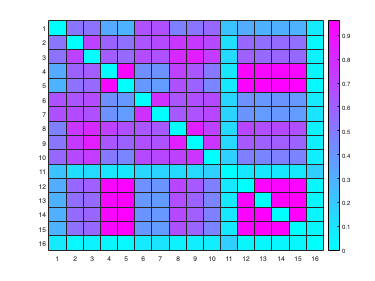

na =   networkAnalyzer with properties:

    spikeTrains: []
       channels: [16×1 containers.Map]
    channelList: [16×1 double]
      nChannels: 16
        distMat: [16×16 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [16×5 double]
     syncScores: [16×16 table]
      nConnects: []
          thres: 0.5000


thres = 0.5; %sync score 0.5 이상일 경우에만 연결된 것으로 간주 (network를 그릴 때에만 적용됨)
na.spikeDist(thres);

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

ans = 16×16 table
               node1       node2       node3       node4       node5       node6       node7      node8       node9       node10      node11      node12      node13      node14      node15      node16 
              ________    ________    ________    ________    ________    ________    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________

    node1       


max(na.syncScores{:,:}) %각 channel별 sync score 최댓값

ans =     0.6573    0.7516    0.8502    0.9368    0.9574    0.7738    0.7738    0.8447    0.8502    0.7608    0.2222    0.9450    0.9591    0.9608    0.9608    0.1818



max(max(na.syncScores{:,:})) %전체 sync score 중 최댓값

ans = 0.9608

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na.nConnects

ans = 16×1 table
              number of connected
              ___________________

    node1              6         
    node2             13         
    node3             13         
    node4             10         
    node5              9         
    node6              7         
    node7              7         
    node8             12         
    node9             13         
    node10             8         
    node11             0         
    node12             9         
    node13             9         
    node14             9         
    node15             9         
    node16             0         


max(na.nConnects{:,:}) %각 channel별 degree 최댓값

ans = 13


max(max(na.nConnects{:,:})) %전체 degree 중 최댓값

ans = 13

## **1**.8. network plot 그리기(2d)

figure 3 a, b, c, d, e의 (ii)

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

#### 파라미터 설정

- node_size_basic

- node_size_multiplier

- startcolor_edge

- endcolor_edge

- startcolor_node

- endcolor_node

- degree_lim

- edge_lim

- edge_colorbar_lim

- community_colorbar_max

- display_community_color

- display_degree

- display_sync_score

- camera_up

- camera_center

- camera_eye

#### Node size parameters

- 노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. node size = (node_size_basic + node_size_multiplier * ( 1 + relative_degree) )

- relative_degree = max degree = 1, min degree = 0으로 normalize

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

#### Colorscale paramters

- edge, node의 colorscale 의 시작과 끝 색깔 코드를 hex code로 입력합니다. 저는 하늘색에서 시작해 남색에서 끝나는 것으로 했습니다.

- https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

%3
startcolor_edge = '#9fcbee';

%4
endcolor_edge =  '#01016f';

%5
startcolor_node = '#9fcbee';

%6
endcolor_node =  '#01016f';

#### Display range paramters

%7
degree_lim = [0, 13]; %Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.

%8
edge_lim = [0.5, 1]; % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

#### Colarbar range paramters

%9
edge_colorbar_lim = [0.5, 1]; % 여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다. edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.

%10
community_colorbar_max = 4; % 여러 plot의 node colorbar 범위를 통일시키기 위한 기능입니다. degree가 아니라 comunity number를 의미합니다.
%예를 들어, 이 값을 20으로 설정하면 colorbar에서 community 번호의 범위가 1-20이 되고, 20번 커뮤니티에 가장 진한 색이 배정됩니다.
% Community는 louvain algorithm을 돌려야 알 수있으므로, 우선 큰 값으로 설정하고 코드를 끝까지 실행하신 다음,
% 생성되는 community_info.csv 파일을 보고 값을 조정하여 이 섹션만 다시 실행하시면 됩니다.

#### Display on/off options

%11
display_community_color= true;

%12
display_degree = true;

%13
display_sync_score = true;

%14
display_axes = false;

#### Camera options

- [https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서

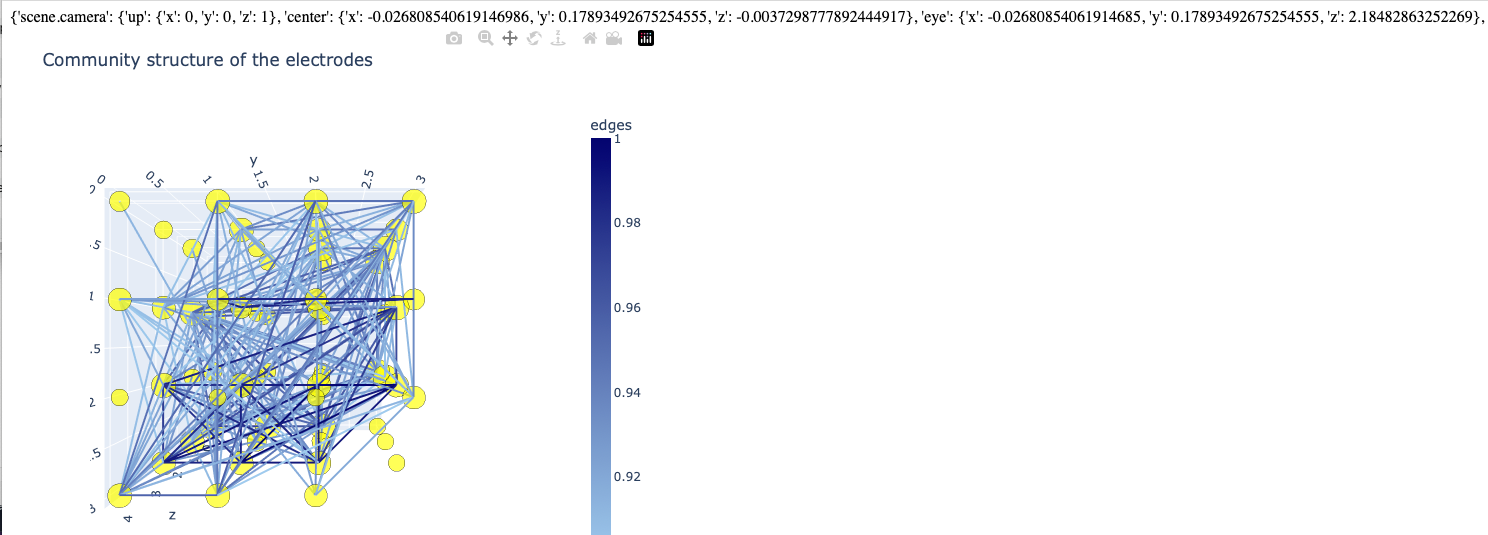

    up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- up은 orbital rotation 기능을 사용하면 바뀌는 값입니다. 2d network에서는 사용할 일이 없습니다.

            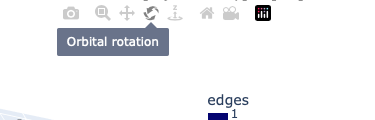

- center는 pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- eye는 turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

nter':  'eye': {

%15
camera_up = [0,0,1];

%16
camera_center = [ -0.026808540619146986, 0.17893492675254555, -0.0037298777892444917];

%17
camera_eye = [-0.02680854061914685,  0.17893492675254555, 2.18482863252269]; %2d 네트워크를 위에서 볼 때는 eye 값은 이 값을 사용합니다.

- 위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다.

- 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

                            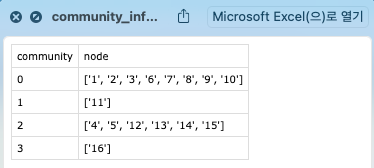

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

                            

na.louvain(node_size_basic, node_size_multiplier, startcolor_edge, endcolor_edge , startcolor_node, endcolor_node,degree_lim, edge_lim, edge_colorbar_lim, community_colorbar_max, display_community_color, display_degree, display_sync_score, display_axes, camera_up, camera_center, camera_eye)

ans = 0

# **2. 3d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **2.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/mac/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 소요시간 측정

## **2.2. networkAnalyzer 인스턴스 생성**

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9"); %  networkAnalyzer 클래스 인스턴스 생성

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: Terminated
    ExecutionMode: OutOfProcess


## **2.3. 데이터 파일을 networkAnalyzer에 전달 **

na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **2.4. 사용하지 않는 채널 제거**

이 예제에서는 1번, 8번, 64번 채널을 제거하겠습니다.

                %채널 번호
na.deleteChannel(1);

Deleted channal 1


idx_channelList = 1

63 channels left


na.deleteChannel(8);

Deleted channal 8


idx_channelList = 7

62 channels left


na.deleteChannel(64);

Deleted channal 64


idx_channelList = 62

61 channels left


## 2.5. 채널 위치 입력

method `setChannelPosition3d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

x, y 좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

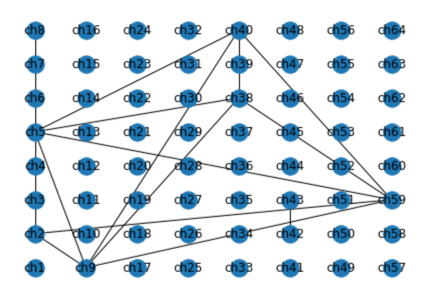

%                 channlNum x  y  z
%na.setChannelPosition3d(1 , 0, 0, 0)
na.setChannelPosition3d(2 , 0, 1, 0)

set channel 2's position as (0.000000, 1.000000, 0.000000)


na.setChannelPosition3d(3 , 0, 2, 0)

set channel 3's position as (0.000000, 2.000000, 0.000000)


na.setChannelPosition3d(4 , 0, 3, 0)

set channel 4's position as (0.000000, 3.000000, 0.000000)


na.setChannelPosition3d(5 , 1, 0, 0)

set channel 5's position as (1.000000, 0.000000, 0.000000)


na.setChannelPosition3d(6 , 1, 1, 0)

set channel 6's position as (1.000000, 1.000000, 0.000000)


na.setChannelPosition3d(7 , 1, 2, 0)

set channel 7's position as (1.000000, 2.000000, 0.000000)


%na.setChannelPosition3d(8 , 1, 3, 0)
na.setChannelPosition3d(9 , 2, 0, 0)

set channel 9's position as (2.000000, 0.000000, 0.000000)


na.setChannelPosition3d(10, 2, 1, 0)

set channel 10's position as (2.000000, 1.000000, 0.000000)


na.setChannelPosition3d(11, 2, 2, 0)

set channel 11's position as (2.000000, 2.000000, 0.000000)


na.setChannelPosition3d(12, 2, 3, 0)

set channel 12's position as (2.000000, 3.000000, 0.000000)


na.setChannelPosition3d(13, 3, 0, 0)

set channel 13's position as (3.000000, 0.000000, 0.000000)


na.setChannelPosition3d(14, 3, 1, 0)

set channel 14's position as (3.000000, 1.000000, 0.000000)


na.setChannelPosition3d(15, 3, 2, 0)

set channel 15's position as (3.000000, 2.000000, 0.000000)


na.setChannelPosition3d(16, 3, 3, 0)

set channel 16's position as (3.000000, 3.000000, 0.000000)



na.setChannelPosition3d(17,  0, 0, 1.5)

set channel 17's position as (0.000000, 0.000000, 1.500000)


na.setChannelPosition3d(18,  0, 1, 1.5)

set channel 18's position as (0.000000, 1.000000, 1.500000)


na.setChannelPosition3d(19,  0, 2, 1.5)

set channel 19's position as (0.000000, 2.000000, 1.500000)


na.setChannelPosition3d(20,  0, 3, 1.5)

set channel 20's position as (0.000000, 3.000000, 1.500000)


na.setChannelPosition3d(21,  1, 0, 1.5)

set channel 21's position as (1.000000, 0.000000, 1.500000)


na.setChannelPosition3d(22,  1, 1, 1.5)

set channel 22's position as (1.000000, 1.000000, 1.500000)


na.setChannelPosition3d(23,  1, 2, 1.5)

set channel 23's position as (1.000000, 2.000000, 1.500000)


na.setChannelPosition3d(24,  1, 3, 1.5)

set channel 24's position as (1.000000, 3.000000, 1.500000)


na.setChannelPosition3d(25,  2, 0, 1.5)

set channel 25's position as (2.000000, 0.000000, 1.500000)


na.setChannelPosition3d(26,  2, 1, 1.5)

set channel 26's position as (2.000000, 1.000000, 1.500000)


na.setChannelPosition3d(27,  2, 2, 1.5)

set channel 27's position as (2.000000, 2.000000, 1.500000)


na.setChannelPosition3d(28,  2, 3, 1.5)

set channel 28's position as (2.000000, 3.000000, 1.500000)


na.setChannelPosition3d(29,  3, 0, 1.5)

set channel 29's position as (3.000000, 0.000000, 1.500000)


na.setChannelPosition3d(30,  3, 1, 1.5)

set channel 30's position as (3.000000, 1.000000, 1.500000)


na.setChannelPosition3d(31,  3, 2, 1.5)

set channel 31's position as (3.000000, 2.000000, 1.500000)


na.setChannelPosition3d(32,  3, 3, 1.5)

set channel 32's position as (3.000000, 3.000000, 1.500000)



na.setChannelPosition3d(33,  0, 0, 3)

set channel 33's position as (0.000000, 0.000000, 3.000000)


na.setChannelPosition3d(34,  0, 1, 3)

set channel 34's position as (0.000000, 1.000000, 3.000000)


na.setChannelPosition3d(35,  0, 2, 3)

set channel 35's position as (0.000000, 2.000000, 3.000000)


na.setChannelPosition3d(36,  0, 3, 3)

set channel 36's position as (0.000000, 3.000000, 3.000000)


na.setChannelPosition3d(37,  1, 0, 3)

set channel 37's position as (1.000000, 0.000000, 3.000000)


na.setChannelPosition3d(38,  1, 1, 3)

set channel 38's position as (1.000000, 1.000000, 3.000000)


na.setChannelPosition3d(39,  1, 2, 3)

set channel 39's position as (1.000000, 2.000000, 3.000000)


na.setChannelPosition3d(40,  1, 3, 3)

set channel 40's position as (1.000000, 3.000000, 3.000000)


na.setChannelPosition3d(41,  2, 0, 3)

set channel 41's position as (2.000000, 0.000000, 3.000000)


na.setChannelPosition3d(42,  2, 1, 3)

set channel 42's position as (2.000000, 1.000000, 3.000000)


na.setChannelPosition3d(43,  2, 2, 3)

set channel 43's position as (2.000000, 2.000000, 3.000000)


na.setChannelPosition3d(44,  2, 3, 3)

set channel 44's position as (2.000000, 3.000000, 3.000000)


na.setChannelPosition3d(45,  3, 0, 3)

set channel 45's position as (3.000000, 0.000000, 3.000000)


na.setChannelPosition3d(46,  3, 1, 3)

set channel 46's position as (3.000000, 1.000000, 3.000000)


na.setChannelPosition3d(47,  3, 2, 3)

set channel 47's position as (3.000000, 2.000000, 3.000000)


na.setChannelPosition3d(48,  3, 3, 3)

set channel 48's position as (3.000000, 3.000000, 3.000000)


na.setChannelPosition3d(49, 0, 0, 4.5)

set channel 49's position as (0.000000, 0.000000, 4.500000)


na.setChannelPosition3d(50, 0, 1, 4.5)

set channel 50's position as (0.000000, 1.000000, 4.500000)


na.setChannelPosition3d(51, 0, 2, 4.5)

set channel 51's position as (0.000000, 2.000000, 4.500000)


na.setChannelPosition3d(52, 0, 3, 4.5)

set channel 52's position as (0.000000, 3.000000, 4.500000)


na.setChannelPosition3d(53, 1, 0, 4.5)

set channel 53's position as (1.000000, 0.000000, 4.500000)


na.setChannelPosition3d(54, 1, 1, 4.5)

set channel 54's position as (1.000000, 1.000000, 4.500000)


na.setChannelPosition3d(55, 1, 2, 4.5)

set channel 55's position as (1.000000, 2.000000, 4.500000)


na.setChannelPosition3d(56, 1, 3, 4.5)

set channel 56's position as (1.000000, 3.000000, 4.500000)


na.setChannelPosition3d(57, 2, 0, 4.5)

set channel 57's position as (2.000000, 0.000000, 4.500000)


na.setChannelPosition3d(58, 2, 1, 4.5)

set channel 58's position as (2.000000, 1.000000, 4.500000)


na.setChannelPosition3d(59, 2, 2, 4.5)

set channel 59's position as (2.000000, 2.000000, 4.500000)


na.setChannelPosition3d(60, 2, 3, 4.5)

set channel 60's position as (2.000000, 3.000000, 4.500000)


na.setChannelPosition3d(61, 3, 0, 4.5)

set channel 61's position as (3.000000, 0.000000, 4.500000)


na.setChannelPosition3d(62, 3, 1, 4.5)

set channel 62's position as (3.000000, 1.000000, 4.500000)


na.setChannelPosition3d(63, 3, 2, 4.5)

set channel 63's position as (3.000000, 2.000000, 4.500000)


%na.setChannelPosition3d(64, 3, 3, 4.5)

## 2.6. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

na.bandPass([300,3000])
na.detectSpikes(4.5,2,2);

channel 2 number of spikes found : 83
channel 3 number of spikes found : 108
channel 4 number of spikes found : 228
channel 5 number of spikes found : 280
channel 6 number of spikes found : 59
channel 7 number of spikes found : 60
channel 9 number of spikes found : 121
channel 10 number of spikes found : 75
channel 11 number of spikes found : 14
channel 12 number of spikes found : 239
channel 13 number of spikes found : 265
channel 14 number of spikes found : 251
channel 15 number of spikes found : 282
channel 16 number of spikes found : 5
channel 17 number of spikes found : 137
channel 18 number of spikes found : 61
channel 19 number of spikes found : 237
channel 20 number of spikes found : 270
channel 21 number of spikes found : 269
channel 22 number of spikes found : 34
channel 23 number of spikes found : 56
channel 24 number of spikes found : 28
channel 25 number of spikes found : 52
channel 26 number of spikes found : 63
channel 27 number of spikes found : 99
channel 28 number of 

## **2.7. sync score 계산 및 확인**

figure 3 a, b, c, d, e의 (i)

pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

아래 사항은 아직 구현하지 않았습니다(reference 12페이지에 있는 내용) 

Since two spike trains with uniformly random activity may exhibit relatively high synchrony merely due to randomness, the SPIKE-distance from recorded data was normalized to random samples generated computationally. That is, for a pair of electrodes with $n_1$ and $n_2$ spikes,

- random spike trains were generated by **sampling $n_1$ and $n_2$ points uniformly at random in a 10-minute timeline.**

- This process was **repeated 1,000 times**, and the **average normalized score** is reported.

- thres 값을 0.9로 설정하면, sync score 0.9 이상일 경우에만 연결된 것으로 간주합니다.

thres = 0.9

thres = 0.9000

na =   networkAnalyzer with properties:

    spikeTrains: []
       channels: [61×1 containers.Map]
    channelList: [61×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [61×5 double]
     syncScores: []
      nConnects: []
          thres: 0.9000


filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.npy"

filepath_positions = "/Users/mac/GitHub/neurosignal-matlab/positions.pkl"

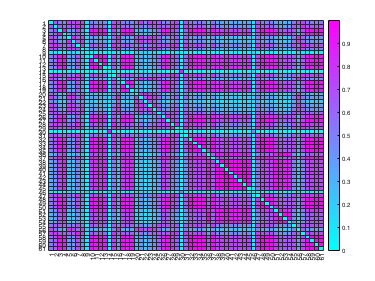

na =   networkAnalyzer with properties:

    spikeTrains: []
       channels: [61×1 containers.Map]
    channelList: [61×1 double]
      nChannels: 61
        distMat: [61×61 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [61×5 double]
     syncScores: [61×61 table]
      nConnects: []
          thres: 0.9000


ans =          0    0.6806    0.5273    0.4518    0.7324    0.6993    0.7549    0.7342    0.1237    0.5093    0.4713    0.4910    0.4493    0.0227    0.6636    0.7361    0.5062    0.4646    0.4659    0.5641    0.7482    0.4865    0.7407    0.7260    0.6703    0.4785    0.5382    0.6816    0.7282    0.0230    0.6769    0.5359    0.5400    0.5400    0.5243    0.2983    0.5583    0.3573    0.3593    0.3512    0.3433    0.3447    0.3298    0.3412    0.3484    0.0870    0.6638    0.5342    0.5294    0.5307
    0.6806         0    0.6369    0.5464    0.6467    0.6310    0.8297    0.7213    0.0984    0.6110    0.5684    0.5905    0.5436    0.0354    0.7837    0.6391    0.6145    0.5608    0.5623    0.4789    0.5854    0.4118    0.6375    0.6433    0.6860    0.5869    0.6503    0.7823    0.7545    0.0179    0.7182    0.6465    0.6523    0.6523    0.6347    0.3732    0.6688    0.4421    0.4435    0.4350    0.4277    0.4283    0.4096    0.4251    0.4286    0.0684    0.7315    0.6446    0.6405   

na.spikeDist(thres)

### network mapping 을 위해 계산하는 parameter 확인

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

ans = 61×61 table
               node1       node2       node3       node4       node5      node6       node7       node8      node9       node10      node11      node12      node13      node14      node15      node16      node17      node18      node19     node20      node21     node22      node23      node24      node25      node26      node27      node28      node29      node30       node31      node32      node33      node3

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na.nConnects

ans = 61×1 table
              number of connected
              ___________________

    node1              0         
    node2              0         
    node3             17         
    node4              5         
    node5              0         
    node6              0         
    node7              0         
    node8              0         
    node9              0         
    node10            21         
    node11            11         
    node12            19         
    node13             6         
    node14             0         
    node15             0         
    node16             0         


max(na.syncScores{:,:}) %각 channel별 sync score 최댓값

ans =     0.7549    0.8297    0.9577    0.9537    0.8571    0.8571    0.8907    0.7704    0.2083    0.9551    0.9468    0.9551    0.9537    0.8889    0.8736    0.8065    0.9538    0.9196    0.9209    0.8065    0.8333    0.8065    0.8333    0.8065    0.7299    0.8758    0.9705    0.8736    0.8413    0.8889    0.8304    0.9864    0.9954    0.9954    0.9844    0.9891    0.9451    0.9881    0.9934    0.9961    0.9961    0.9987    0.9807    0.9987    0.9896    0.4615    0.8367    0.9888    0.9910    0.9867



max(max(na.syncScores{:,:})) %전체 sync score 중 최댓값

ans = 0.9987


na.nConnects

ans = 61×1 table
              number of connected
              ___________________

    node1              0         
    node2              0         
    node3             17         
    node4              5         
    node5              0         
    node6              0         
    node7              0         
    node8              0         
    node9              0         
    node10            21         
    node11            11         
    node12            19         
    node13             6         
    node14             0         
    node15             0         
    node16             0         


max(na.nConnects{:,:}) %각 channel별 degree 최댓값

ans = 21


max(max(na.nConnects{:,:})) %전체 degree 중 최댓값

ans = 21

## 2.8. network plot 그리기(3d)

figure 3 a, b, c, d, e의 (ii)

matlab에서 python을 통해 networkx로 네트워크를 만들고 louvain-python으로 community detection을 하는 것까지는 별 문제가 없으나,

네트워크 모양을 plot으로 그리는 것은 matplotlib 라이브러리를 써야 하는데, 이상하게도 matlab에서 연동이 잘 안됩니다.

차선책으로, score matrix를 파일로 저장한 다음 아예 파이썬 스크립트를 만들고 matlab에서는 해당 파이썬 스크립트를 실행하는 명령만 내리도록 조치하였습니다.

plot은 이 파일이 있는 경로에 `networkfig.html`로 저장됩니다.

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

#### 파라미터 설정

- node_size_basic

- node_size_multiplier

- startcolor_edge

- endcolor_edge

- startcolor_node

- endcolor_node

- degree_lim

- edge_lim

- edge_colorbar_lim

- community_colorbar_max

- display_community_color

- display_degree

- display_sync_score

- camera_up

- camera_center

- camera_eye

#### Node size parameters

- 노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. node size = (node_size_basic + node_size_multiplier * ( 1 + relative_degree) )

- relative_degree = max degree = 1, min degree = 0으로 normalize

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

####  Colorscale paramters

- Edge와 node의 colorscale 의 시작과 끝 색깔 코드를 hex code로 입력합니다. 저는 하늘색에서 시작해 남색에서 끝나는 것으로 했습니다.

- Hex code는 https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

startcolor_edge = '#9fcbee';
endcolor_edge =  '#01016f';
startcolor_node = '#9fcbee';
endcolor_node =  '#01016f';

#### Display range paramters

degree_lim = [0, 20]; %Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.
edge_lim = [0.9, 1]; % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

#### Colarbar range paramters

edge_colorbar_lim = [0.9, 1]; % 여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다. edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.
community_colorbar_max = 30; % 여러 plot의 node colorbar 범위를 통일시키기 위한 기능입니다. degree가 아니라 comunity number를 의미합니다.
%예를 들어, 이 값을 20으로 설정하면 colorbar에서 community 번호의 범위가 1-20이 되고, 20번 커뮤니티에 가장 진한 색이 배정됩니다.
% Community는 louvain algorithm을 돌려야 알 수있으므로, 우선 큰 값으로 설정하고 코드를 끝까지 실행하신 다음,
% 생성되는 community_info.csv 파일을 보고 값을 조정하여 이 섹션만 다시 실행하시면 됩니다.

#### Display on/off options

display_community_color= true;
display_degree = true;
display_sync_score = true;
display_axes = true;

#### Camera options

- [https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서

    up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- up은 orbital rotation 기능을 사용하면 바뀌는 값입니다.

            

- center는 pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- eye는 turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

camera_up = [0,0,1];
camera_center = [-0.10098346615340659,0.08859588059353385,  0.012387585559872738];
camera_eye = [1.7980575942618118, 0.12853842060263704, -1.374004869994737];

- 위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다.

- 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

na.louvain(node_size_basic, node_size_multiplier, startcolor_edge, endcolor_edge, startcolor_node, endcolor_node,  degree_lim, edge_lim, edge_colorbar_lim, community_colorbar_max, display_community_color, display_degree, display_sync_score, display_axes, camera_up, camera_center, camera_eye)

ans = 0